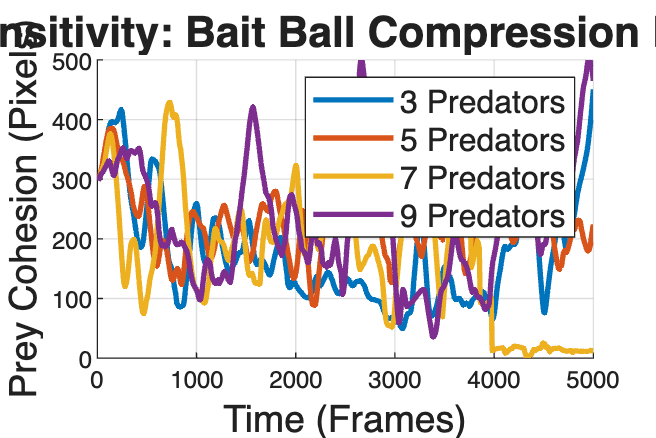

% Plot 1 - Bait Ball Comparison (impact of predator count)
% Load Data
clear; clc; close all;

% Define the files (Make sure these match your CSV filenames exactly)
files = {'cohesion_timeseries_3_predators.csv', ...
         'cohesion_timeseries_5_predators.csv', ...
         'cohesion_timeseries_7_predators.csv', ...
         'cohesion_timeseries_9_predators.csv'};
     
labels = {'3 Predators', '5 Predators', '7 Predators', '9 Predators'};

% Colors
colors = [
    0.00, 0.45, 0.74;  
    0.85, 0.33, 0.10;  
    0.93, 0.69, 0.13;  
    0.49, 0.18, 0.56   
];

% Generate Plot
figure('Name', 'Sensitivity Dynamics', 'Color', 'w', 'Position', [100, 100, 900, 600]);
hold on;

% Loop through files and plot
for i = 1:length(files)
    % Read table
    T = readtable(files{i});
    
    % Plot Model 3 Cohesion
    plot(T.frame, T.model3_coordination_cohesion, ...
         'Color', colors(i,:), ...
         'LineWidth', 2.0, ...
         'DisplayName', labels{i});
end

hold off;

%Formatting 
title('Sensitivity: Bait Ball Compression Rate', 'FontSize', 16);
xlabel('Time (Frames)', 'FontSize', 14);
ylabel('Prey Cohesion (Pixels)', 'FontSize', 14);

% Legend
lgd = legend('Location', 'northeast');
lgd.FontSize = 12;

% Standard Grid
grid on;

% Set limits
xlim([0 5000]); 
ylim([0 500]);

saveas(gcf, 'Sensitivity_Dynamics_Simple.png');

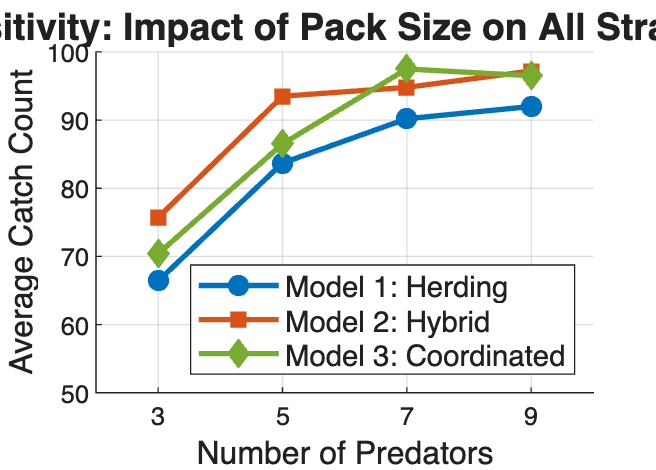

% Plot 2 - Impact of pack size on predation efficiency
% Load Data
clear; clc; close all;

% Define files and corresponding counts
files = {'benchmark_results_3predators.csv', 'benchmark_results_5predators.csv', ...
         'benchmark_results_7preds.csv', 'benchmark_results_9predators.csv'};
counts = [3, 5, 7, 9];

means_m1 = zeros(1, 4);
means_m2 = zeros(1, 4);
means_m3 = zeros(1, 4);

% Loop through each file
for i = 1:4
    data = readtable(files{i});
    
    % Filter by method string
    m1 = data(contains(data.simulation_id, 'method1'), :);
    m2 = data(contains(data.simulation_id, 'method2'), :);
    m3 = data(contains(data.simulation_id, 'method3'), :);
    
    % Calculate averages
    means_m1(i) = mean(m1.boids_caught);
    means_m2(i) = mean(m2.boids_caught);
    means_m3(i) = mean(m3.boids_caught);
end

%Plot Lines
figure('Name', 'Sensitivity Comparison', 'Color', 'w', 'Position', [100, 100, 700, 500]);
hold on;

% Plot Model 1
plot(counts, means_m1, '-o', 'Color', '#0072BD', 'LineWidth', 2, ...
    'MarkerFaceColor', '#0072BD', 'DisplayName', 'Model 1: Herding');

% Plot Model 2 
plot(counts, means_m2, '-s', 'Color', '#D95319', 'LineWidth', 2, ...
    'MarkerFaceColor', '#D95319', 'DisplayName', 'Model 2: Hybrid');

% Plot Model 3
plot(counts, means_m3, '-d', 'Color', '#77AC30', 'LineWidth', 2, ...
    'MarkerFaceColor', '#77AC30', 'DisplayName', 'Model 3: Coordinated');

hold off;

%Formatting
title('Sensitivity: Impact of Pack Size on All Strategies', 'FontSize', 14);
xlabel('Number of Predators', 'FontSize', 12);
ylabel('Average Catch Count', 'FontSize', 12);

legend('Location', 'southeast', 'FontSize', 11);
xticks(counts); 
grid on;

ylim([50 100]);

saveas(gcf, 'Sensitivity_Comparison_AllModels.png');